# Compressione delle immagini senza perdita d'informazione

In questa demo valutiamo l'entropia delle immagini per stimare le prestazioni di un possibile algoritmo di compressione senza perdita d'informazione.

Carichiamo e mostriamo un'immagine.

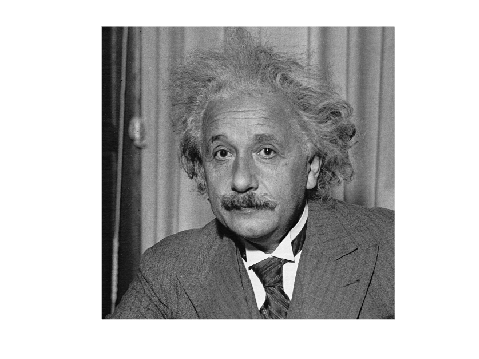

close all; clear variables;
% Load the image 
imageName = "einst";
fileName = sprintf('%s.pgm',imageName);
x= imread(fileName);
% Show the image
figure; imagesc(x); colormap(gray); axis image; axis off; 

Senza applicare compressione, questa immagine a 256 livelli di grigio necessita di 8 bit per pixel (8 bpp).

### Entropia

Calcoliamo l'entropia al livello di pixel. In altre parole, consideriamo una sorgente aleatoria che emette i valori di luminosità dei singoli pixel, e ne stimiamo l'entropia. Ciò si effettua stimando prima la probabilità di ogni "simbolo" emesso da tale sorgente, e cioè la probabilità di ogni livello di grigio. Tale probabilità viene stimata tramite il calcolo della *frequenza relativa.* Dal vettore delle frequenze relative rimuoveremo le eventuali frequenze nulle per non incorrere in problemi di calcolo che avremmo se in un'immagine uno o più valori avessero zero occorrenze. Notare che, siccome $p\;\log_2 \frac{1}{p}\to 0$ per $p\to 0$, ignorare i simboli con probabilità nulla è perfettamente coerente con la definizione di entropia. 

tmp = transpose(x);
rasterScan = tmp(:); % Questo permette di leggere i pixel dell'immagine riga per riga
occorrenze = hist(rasterScan,0:255); % contiamo le occorrenze dei valori
freqRel = occorrenze/sum(occorrenze); % Trasformiamo le occorrenze in frequenze relative
p = freqRel(freqRel>0); %Rimuoviamo eventuali valori nulli di probabilità
HX = p*log2(1./p'); % formula dell'entropia. In Matlab "*" effettua il prodotto scalare
fprintf('L''entropia dell''immagine %s è di %5.3f bpp\n',imageName, HX);

L'entropia dell'immagine einst è di 6.785 bpp


fprintf('Il rapporto di compressione ottenibile è di %5.4f\n',8/HX);

Il rapporto di compressione ottenibile è di 1.1791


Spieghiamo il codice usato per il calcolo dell'entropia (riga 13). In Matlab, l'operatore `*` effettua il *prodotto matriciale. *Nel caso di un vettore riga `x` e un vettore colonna `y` il comando `x*y`  calcola: $\sum_{i=1}^N x\left(i\right)y\left(i\right)$

Ora, il vettore `p` è il vettore riga delle probabilità stimate (frequenze relative), mentre `log2(1./p')` è il vettore *colonna *(perché l'operatore apice `'` effettua la trasposizione, mentre il punto "`.`" prima dell'operatore di divisione serve per indicare la divisione elemento per elemento) dell'informazione. Il prodotto riga per colonna dà $\sum_{i=1}^N p\left(i\right)\log_2 \frac{1}{p\left(i\right)}$, cioè esattamente la stima dell'entropia. 

### Codifica con dizionario ("zip")

Utilizziamo un codificatore con dizionario per effettuare una codifica lossless dell'immagine. Useremo il software "zip" disponibile in Windows. Se si usa un altro SO, bisognerà utilizzare il software adeguato con le opportune opzioni (p.e., `gzip`).

cmd = sprintf('zip %s %s.pgm', imageName, imageName); % crea la stringa di comando
system(cmd); % la invia al SO per esecuzione

  adding: einst.pgm (200 bytes security) (deflated 20%) 


info=dir(sprintf('%s.zip',imageName));
nBytes = info.bytes; % recupera la dimensione del file ZIP
zip_bpp = nBytes*8/512/512 % dmensione espressa in bpp

zip_bpp = 6.3916

Il tasso di codifica risulta generalmente inferiore all'entropia perché la codifica con dizionario sfrutta la ripetizione di stringhe di simboli, e quindi il limite teorico è l'entropia di blocchi di simboli, che in un segnale che presenta dipendenze statistiche, è inferiore all'entropia del singolo simbolo (una volta normalizzata sul numero di simboli del blocco). 

### Predizione spaziale semplificata

Proviamo ora con la predizione spaziale. Per ogni pixel usiamo come predittore il **valore precedente**. Dopo, calcoliamo l'errore di predizione, cioè la differenza tra predittore e valore vero. Infine, mostriamo l'errore di predizione e poi valutiamone l'entropia.

Matematicamente, detto $x\left(n\right)$ (per $n$ da 1 a $N$) il segnale di luminanza e $p\left(n\right)$ il predittore, si ha

$p\left(n\right)=\left\lbrace \begin{array}{ll}
128 & \textrm{se}\;n=1\\
x\left(n-1\right) & \textrm{se}\;n>1
\end{array}\right.$ e quindi l'errore di predizione è $y\left(n\right)=\left\lbrace \begin{array}{ll}
x\left(1\right)-128 & \textrm{se}\;n=1\\
x\left(n\right)-x\left(n-1\right) & \textrm{se}\;n>1
\end{array}\right.$

Notiamo che il primo pixel dell'immagine (contenuto nella variabile `rasterScan`) non può essere predetto da valori precedenti. Usiamo allora il valore 128 come predizione. Per gli altri pixel, il predittore è il pixel precedente: basterà usare l'operatore `diff` che calcola la differenza tra valori consecutivi. Si noti il *cast *al tipo `double` che in Matlab è necessario per applicare correttamente l'operatore `diff`. Per il resto, il calcolo dell'entropia si esegue come per il caso dell'immagine. 

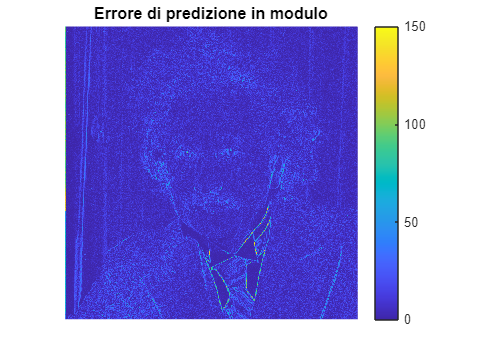

predErr = [double(rasterScan(1))-128; diff(double(rasterScan))];
figure; imagesc(transpose(reshape(abs(predErr),512,512)));  axis image; axis off; colorbar;
title('Errore di predizione in modulo')

occorrenze = hist(predErr,-255:255); % contiamo le occorrenze dei valori
freqRel = occorrenze/sum(occorrenze); % Trasformiamo le occorrenze in frequenze relative
p = freqRel(freqRel>0); %Rimuoviamo eventuali valori nulli di probabilità
HY = p*log2(1./p'); % formula dell'entropia. In Matlab "*" effettua il prodotto scalare
fprintf('L''entropia dell''errore di predizione per %s è di %5.3f bpp\n',imageName, HY);

L'entropia dell'errore di predizione per einst è di 5.395 bpp


fprintf('Il rapporto di compressione ottenibile è di %5.4f\n',8/HY);

Il rapporto di compressione ottenibile è di 1.4830


### Codifica Exp Golomb

Adesso usiamo Exp-Golomb per codificare l'errore di predizione. La codifica* signed EG* è effettuata dalla funzione `expGolombSigned` che a sua volta usa la codifica EG unsigned. Aprendo i file corrispondenti si può verificare che tali funzioni implementano esattamente gli algoritmi EG visti a lezione. 

Una volta prodotta la codeword, ci limitiamo a contarne i bit ed a sommare il valore in un opportuno accumulatore:

bitCount = 0;
for index = 1:numel(predErr)
    symbol = predErr(index);
    codeword = expGolombSigned(symbol);
    bitCount = bitCount + numel(codeword);
end
EG_bpp = bitCount/512/512;
fprintf('Tasso di codifica S-EG su errore di pred.: %5.4f\n',EG_bpp );

Tasso di codifica S-EG su errore di pred.: 6.9466


Confrontiamo il tasso di codifica ottenuto con questa tecnica con l'entropia dell'errore di predizione: la codifica EG mostra una penalizzazione abbastanza forte rispetto all'entropia, che sarebbe invece raggiungibile (con ottima approssimazione) usando un codificatore aritmetico. Il vantaggio della codifica EG sta nella sua grande semplicità implementativa: le prestazioni non sono lontane da quelle di zip (il risultato preciso dipende dall'immagine), ma la complessità d'implementazione è molto inferiore.

### Istogrammi

Mostriamo anche gli istogrammi dell'immagine e dell'errore di predizione per verificarne la sparsità.

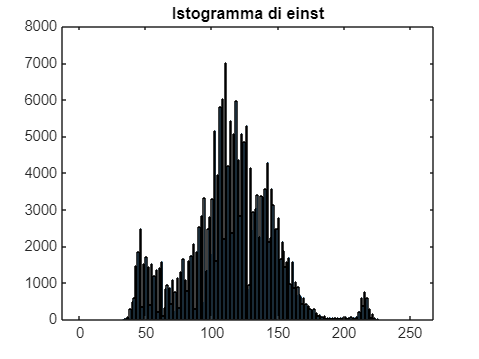

histogram(x,0:255); title(sprintf('Istogramma di %s', imageName))

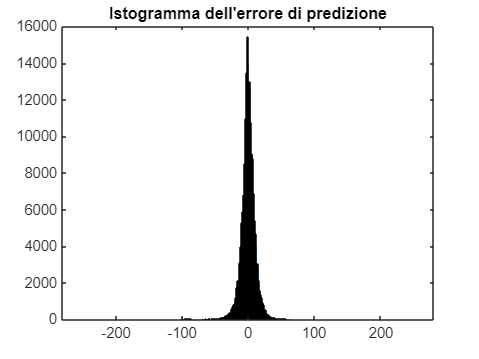


histogram(predErr, -255:255); title('Istogramma dell''errore di predizione'); 

 L'errore di predizione ha un istogramma centrato in zero e piuttosto  "stretto", indice di maggiore *sparsità* del segnale. 

### Riepilogo dei risultati

Salviamo i risultati su file, così possiamo confrontare facilmente quello che accade per le diverse immagini. 

logFileName = 'lossless.txt';
if ~exist(logFileName,'file')
    fid = fopen(logFileName, 'wt');
    fprintf(fid, 'Immagine|  H(X)  | ZIP(X) |  H(Y)  |  EG(Y) | \n');
    fclose(fid);
end
fid = fopen(logFileName, 'at');
fprintf(fid, '%8s|%8.3f|%8.3f|%8.3f|%8.3f|\n',imageName, HX, zip_bpp, HY, EG_bpp );
fclose(fid);

Stampiamo anche a schermo:

fprintf('Immagine|  H(X)  | ZIP(X) |  H(Y)  |  EG(Y) | \n%8s|%8.3f|%8.3f|%8.3f|%8.3f|',imageName, HX, zip_bpp, HY, EG_bpp )

Immagine|  H(X)  | ZIP(X) |  H(Y)  |  EG(Y) | 
   einst|   6.785|   6.392|   5.395|   6.947|